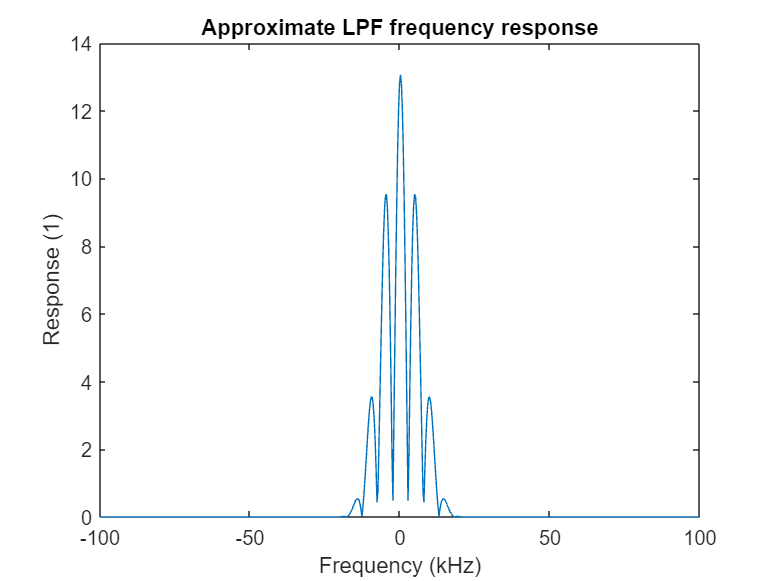

load blackman.mat -mat

figure(1)
nyq = 100000;
v_x1 = window(@hann, length(filter_coef));
y = fft([filter_coef.*v_x1' zeros(1, 600)]);
z = fftshift(y);
plot((-nyq:(2*nyq/(length(z)-1)):nyq)/10^3,abs(real(z)))
xlabel("Frequency (kHz)")
ylabel("Response (1)")
title("Approximate LPF frequency response")

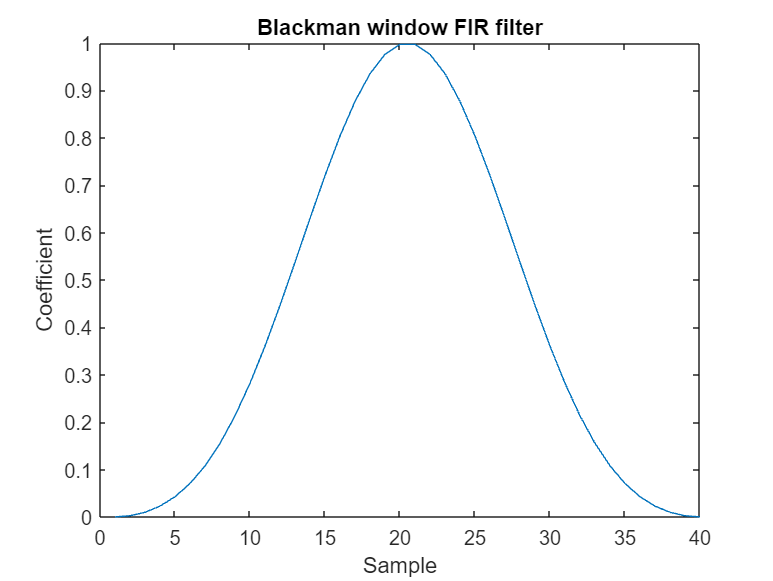


figure(2)
plot(1:length(filter_coef), filter_coef)
xlabel("Sample")
ylabel("Coefficient")
title("Blackman window FIR filter")